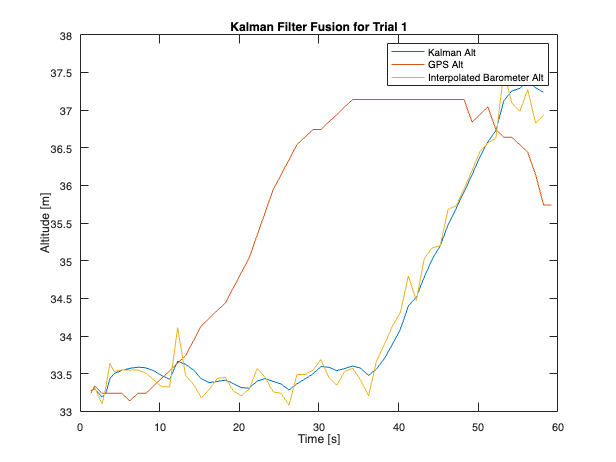

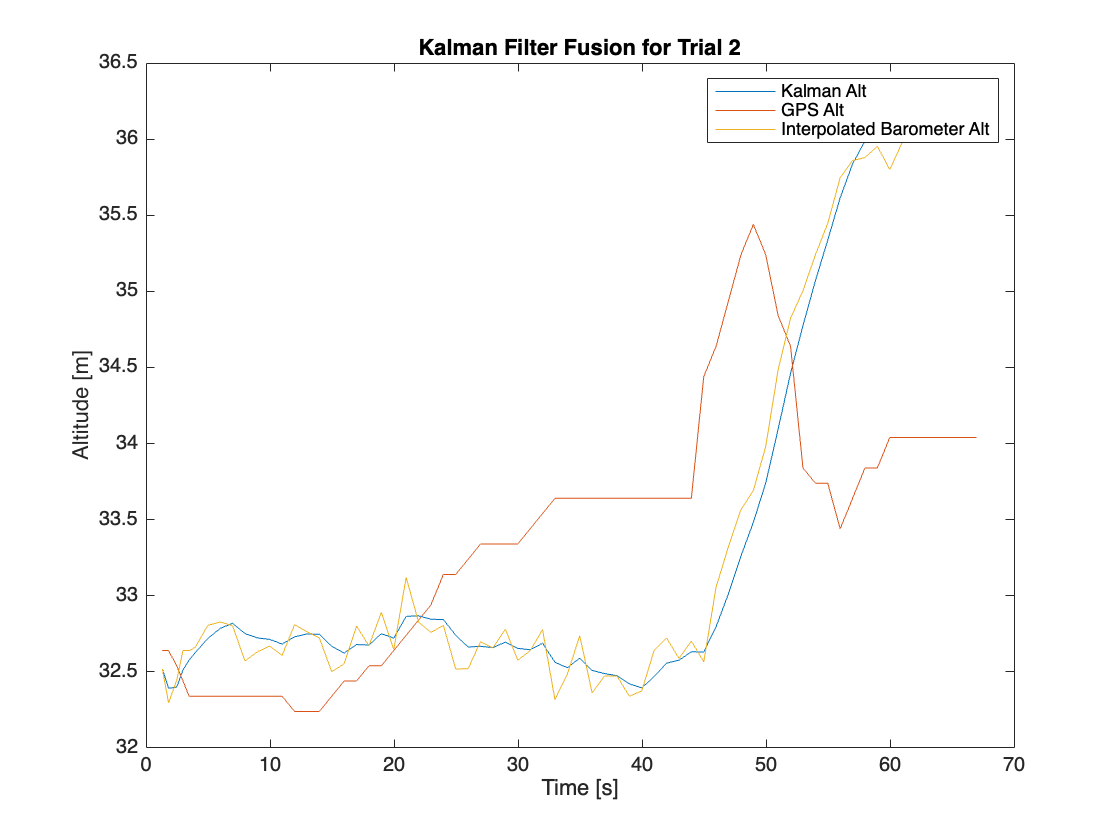

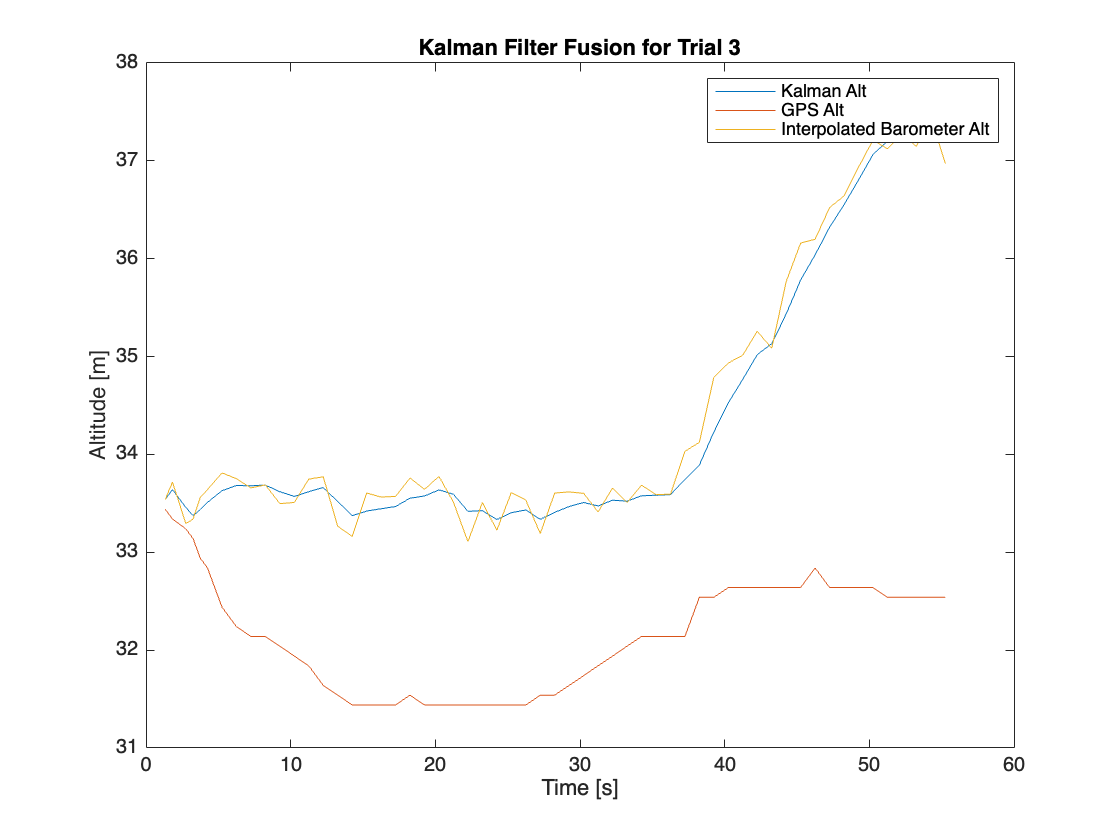

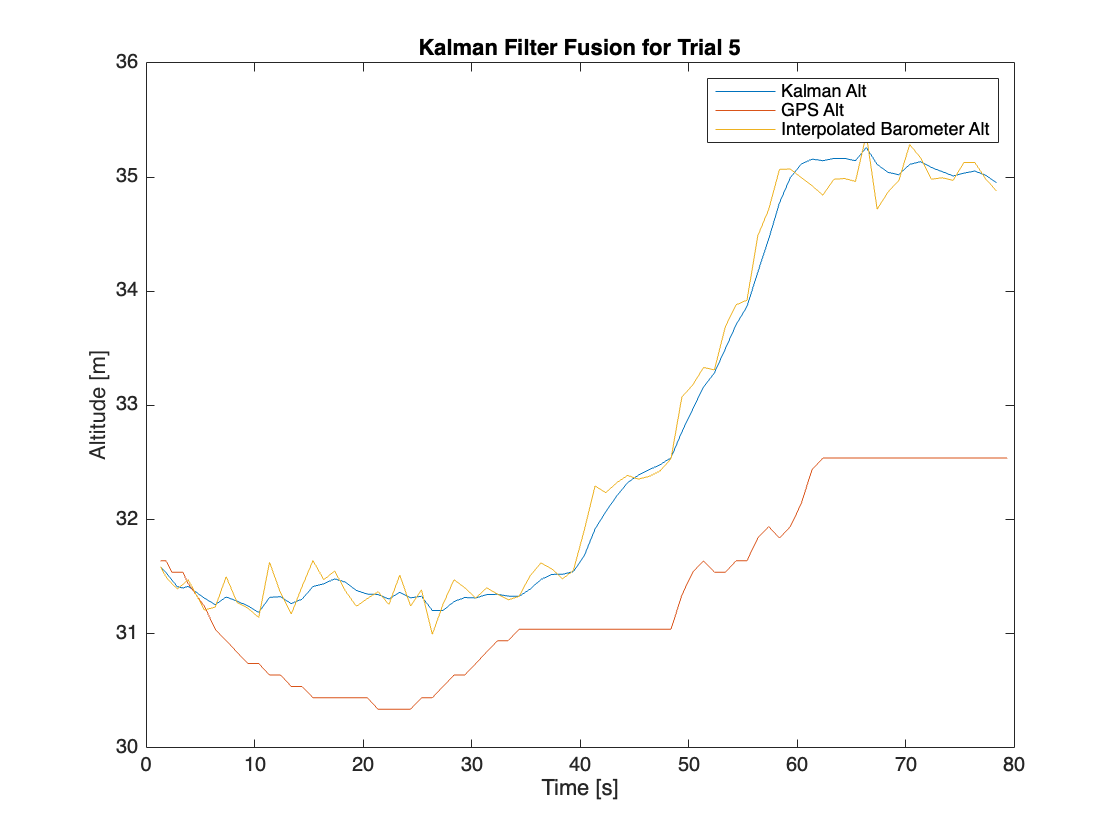

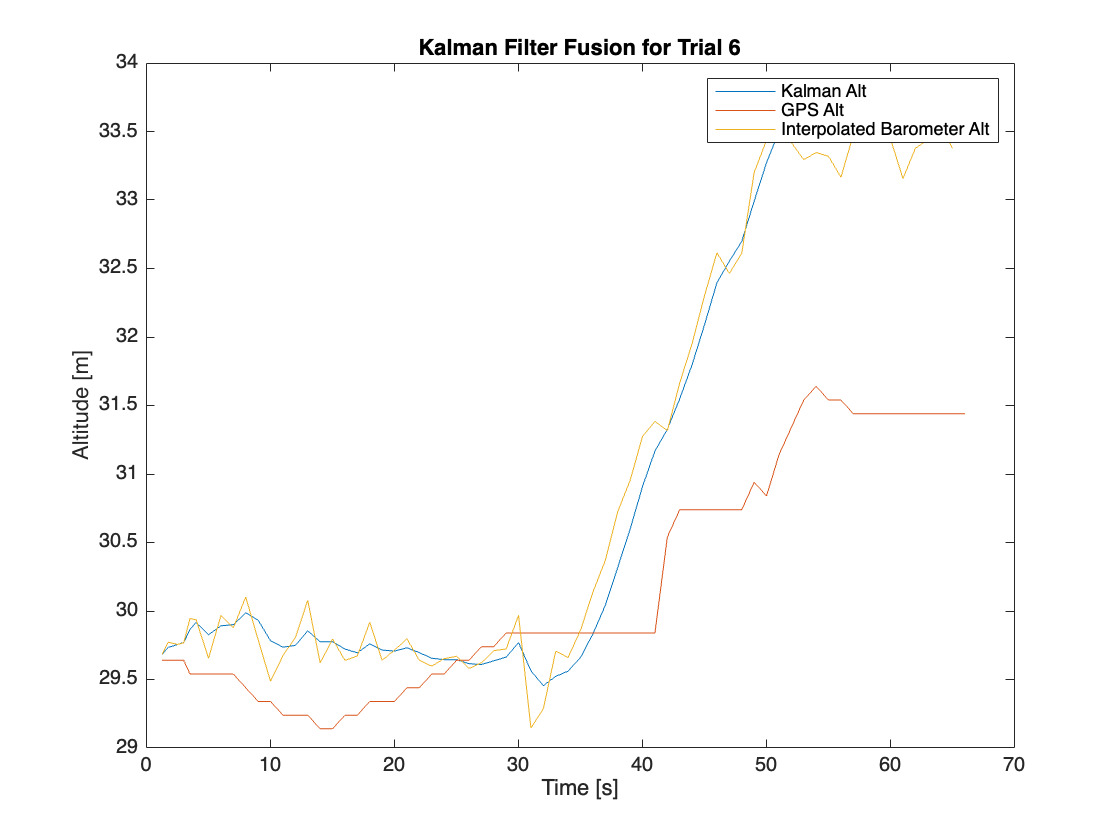

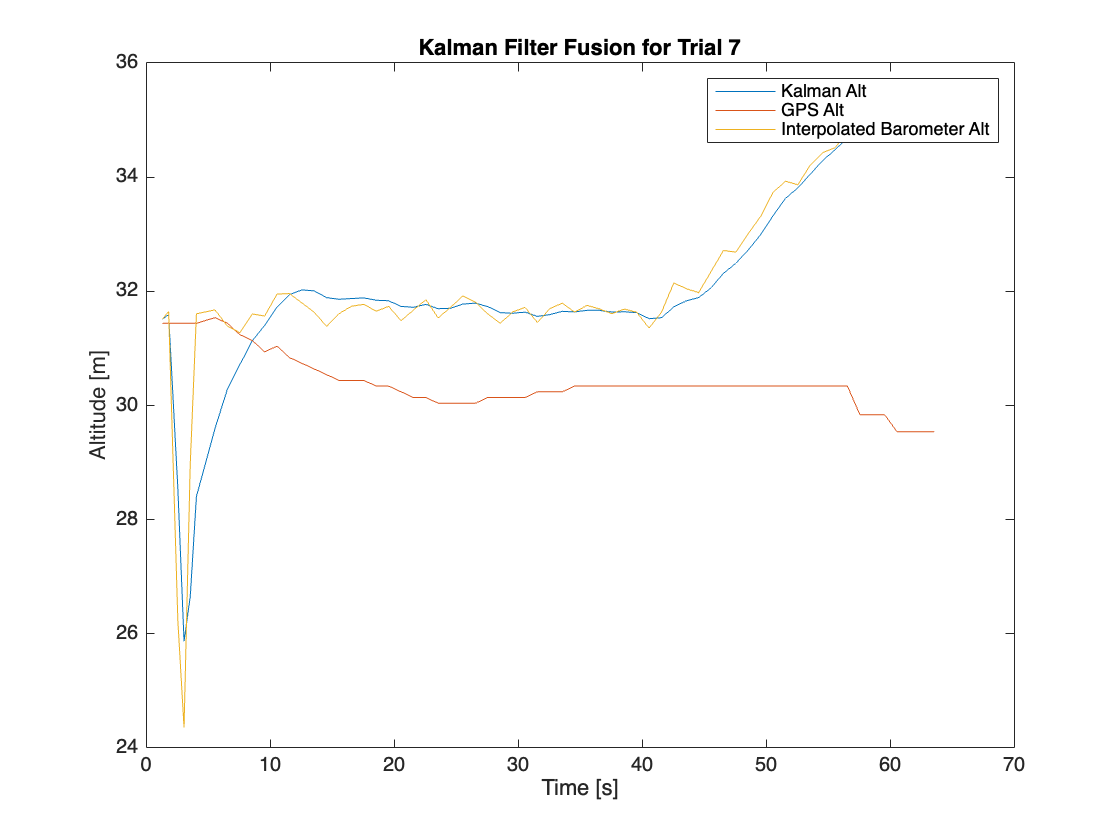

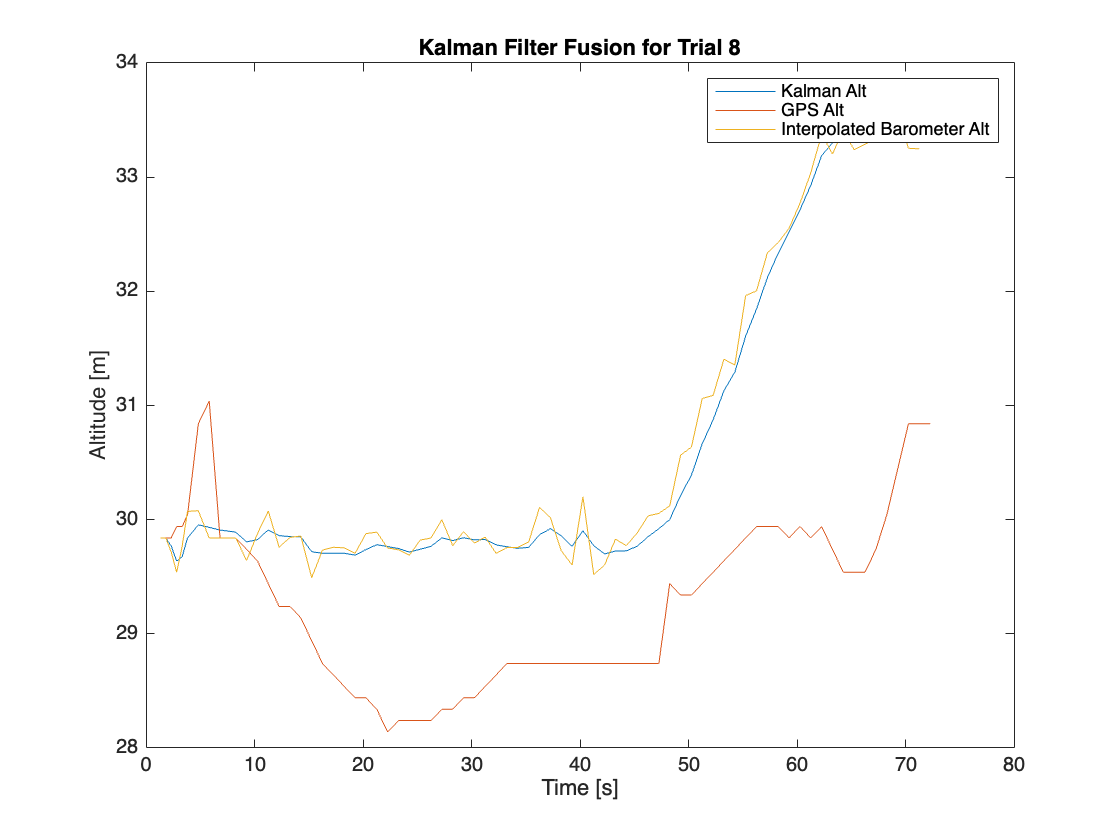

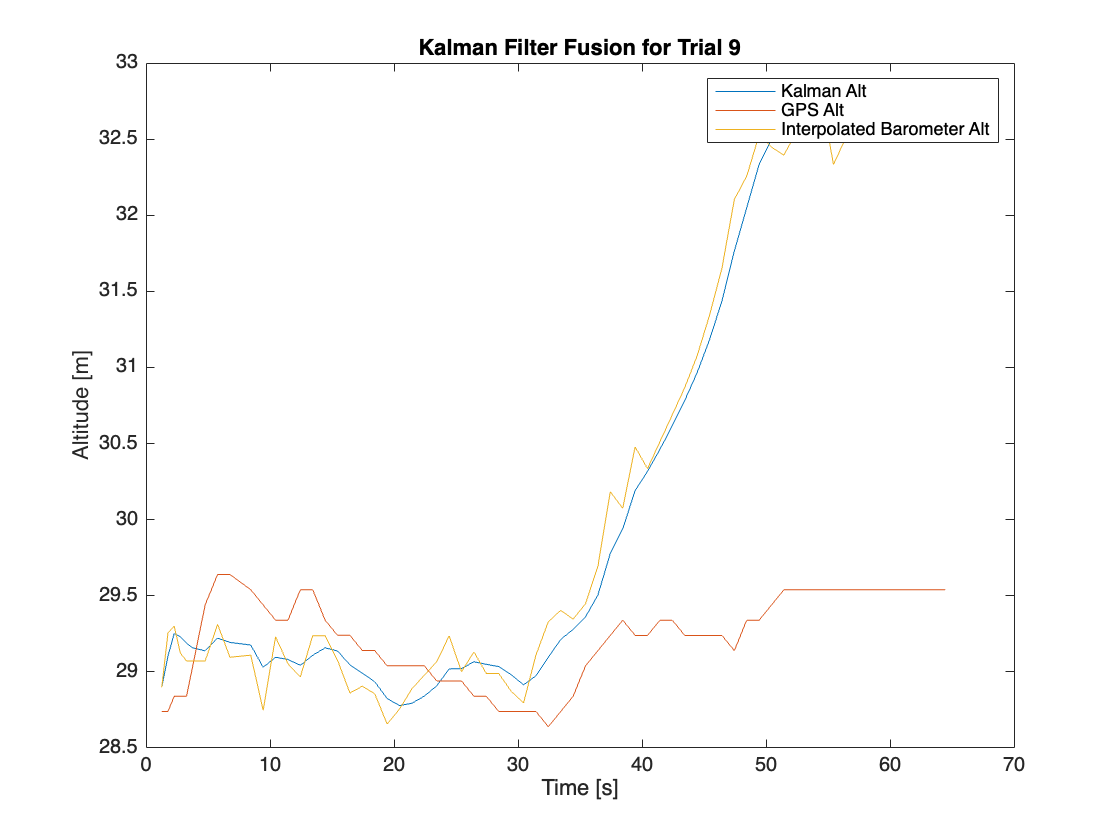

clear all
clf
dataFolder="/Users/alexmescher/Downloads/data";
deltaAlt=[];
endAlt=[];
groundTruthChange=3.5052;
groundTruthABS=34+4.5212;%From google map and measurment
for i=1:31
    trialFolder=dataFolder+"/t"+num2str(i);
    pressureData=readtable(trialFolder+"/Pressure.csv");
    locationData=readtable(trialFolder+"/Location.csv");
    [kalmanAlt,gpsAlt,barAlt,time]=getKalman(pressureData,locationData);
    nonNaNIndices = find(~isnan(kalmanAlt));
    if length(nonNaNIndices)>2
        endAlt=[endAlt,kalmanAlt(nonNaNIndices(end))];
        deltaAlt=[deltaAlt,kalmanAlt(nonNaNIndices(end))-kalmanAlt(nonNaNIndices(1))];
        figure(i)
        plot(time,kalmanAlt)
        hold on
        plot(time,gpsAlt)
        plot(time,barAlt)
        ylabel("Altitude [m]")
        xlabel("Time [s]")
        title("Kalman Filter Fusion for Trial "+num2str(i))
        legend("Kalman Alt","GPS Alt","Interpolated Barometer Alt")
        hold off
    end
end

changeError=deltaAlt-groundTruthChange;
muChangeEr=mean(changeError)

muChangeEr =    0.224852855609658


sigChangeEr=std(changeError)

sigChangeEr =    0.193701253347771


absEr=endAlt-groundTruthABS;
muABSEr=mean(absEr)

muABSEr =   -3.946271073108949


sigABSEr=std(absEr)

sigABSEr =    1.713803451624008


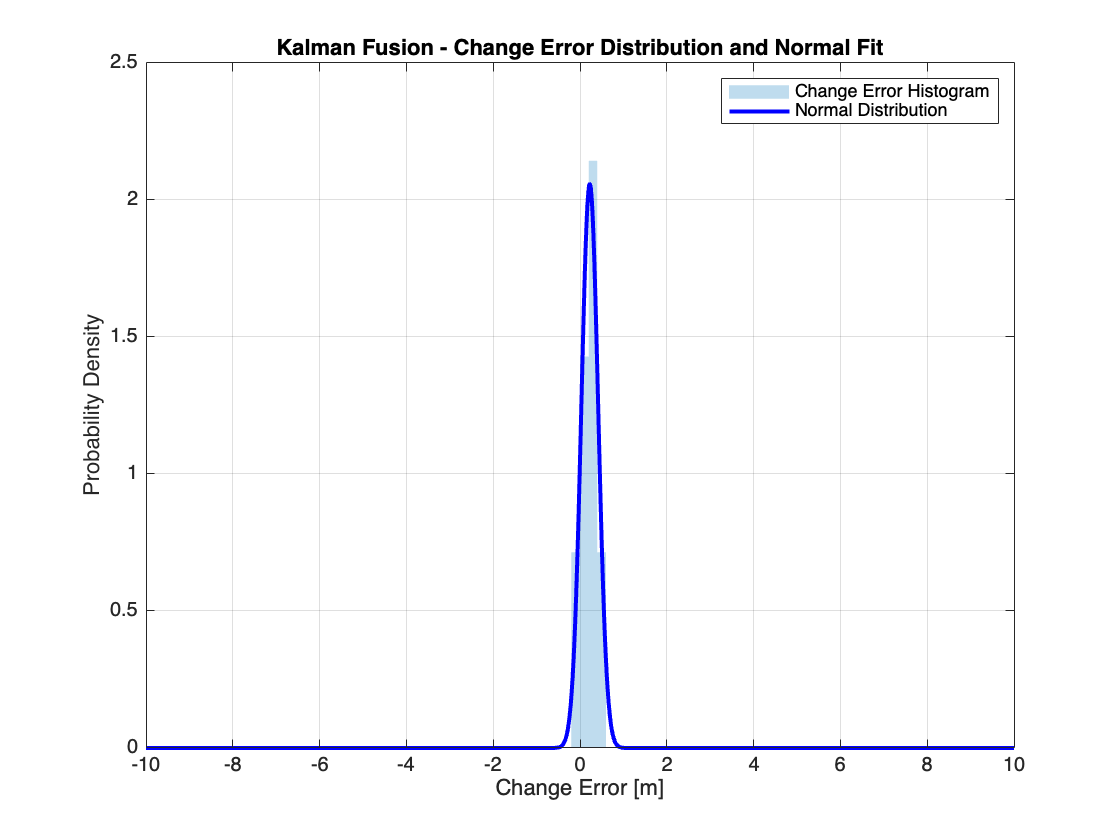


% Define the range of x values for plotting
x = linspace(-10, 10, 1000);

% Calculate the probability density function (pdf) for each normal distribution
pdf1 = normpdf(x, muChangeEr, sigChangeEr);
pdf2 = normpdf(x, muABSEr, sigABSEr);

% Plot the first distribution with histogram of changeError
figure;
histogram(changeError, 'Normalization', 'pdf', 'FaceAlpha', 0.25, 'EdgeColor', 'none');
hold on;
plot(x, pdf1, 'b', 'LineWidth', 2);
xlabel('Change Error [m]');
ylabel('Probability Density');
title('Kalman Fusion - Change Error Distribution and Normal Fit');
legend('Change Error Histogram', sprintf('Normal Distribution', muChangeEr, sigChangeEr));
grid on;
hold off;

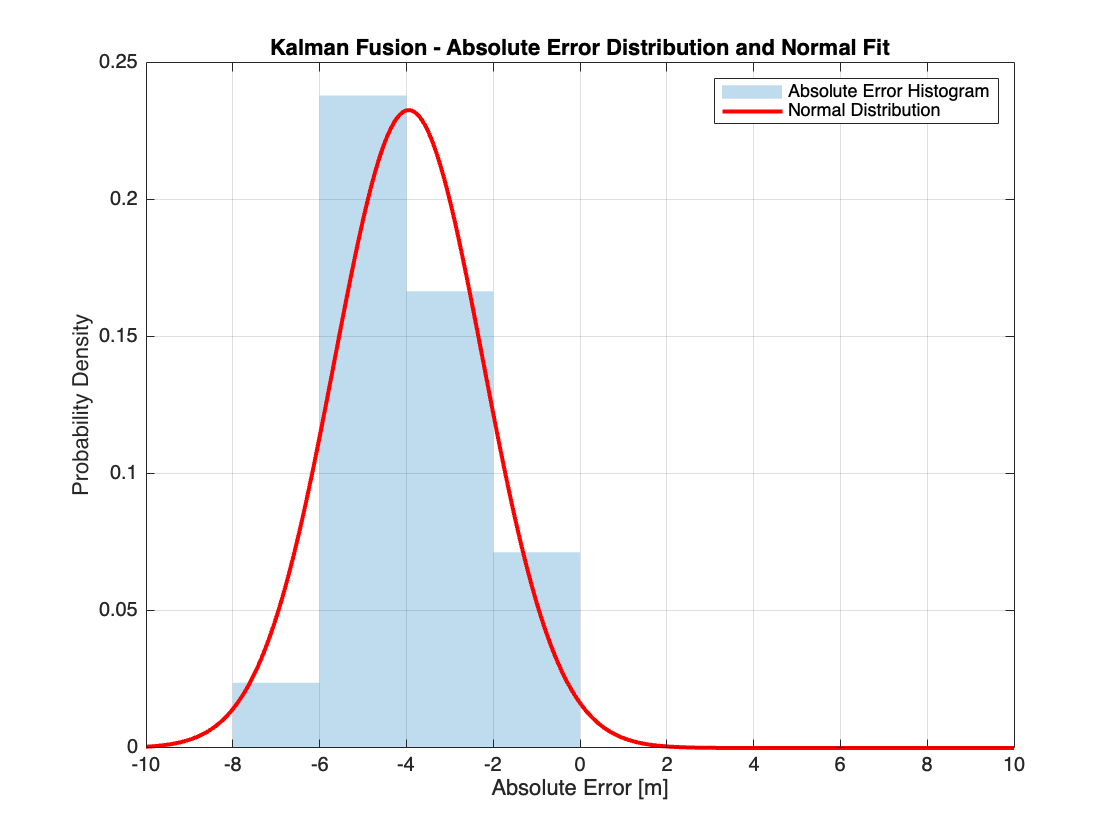


% Plot the second distribution with histogram of absEr
figure;
histogram(absEr, 'Normalization', 'pdf', 'FaceAlpha', 0.25, 'EdgeColor', 'none');
hold on;
plot(x, pdf2, 'r', 'LineWidth', 2);
xlabel('Absolute Error [m]');
ylabel('Probability Density');
title('Kalman Fusion - Absolute Error Distribution and Normal Fit');
legend('Absolute Error Histogram', sprintf('Normal Distribution', muABSEr, sigABSEr));
grid on;
hold off;